# Getting Started with Luenberger Observer Toolbox

## Description

Toolbox for designing and testing Luenberger observers.

## System Requirements

MATLAB R2020b is recommended.

## Features

The toolbox contains functions for assisting in designing Luenberger observers for SISO LTI ODE systems and input-affine nonlinear systems.

## Examples

### Example 1: Estimate the states of LTI ODE plant using Luenberger and output-error injection observer

#### Specify plant and simulation parameters

% LTI plant model
A = [-1 -2; 0 -3;];
B = [1; 2;];
C = [1 0];
H = 0;

% Specify initial conditions
x0 = [1; 3;];

% Input function
u = @(t) sin(t);

% Length of simulation
tsim = 10;

#### Specify Luenberger observer and obtain transformation

% Design observer
D = generateLuenbergerD([(-1 - 1i) (-1 + 1i) -2 ]);
F = [1; 1; 1;];

% Compute Luenberger forward and left-inverse transformations
[T, T_star] = computeLinearLuenbergerT(A,C,D,F);

#### Obtain plant and observer states together with plant state estimates

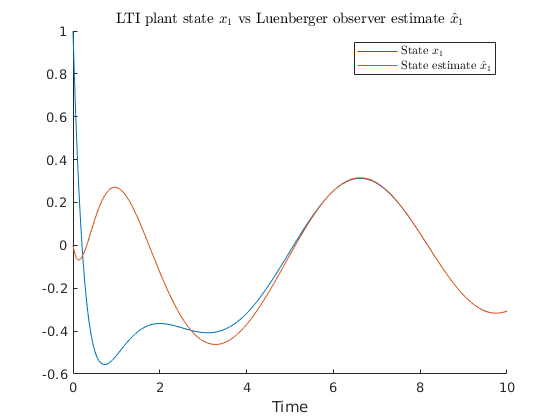

% Simulate system with Luenberger observer
[t_luen, x_hat_luen, x_luen, z] = estimateLinearXLuenberger(A,B,C,H,D,F,x0,tsim,u,T,T_star);

% Plot Luenberger observer results
figure
hold on
plot(t_luen, x_luen(:,1));
plot(t_luen, x_hat_luen(:,1));
title('LTI plant state $x_1$ vs Luenberger observer estimate $\hat{x}_1$', "Interpreter",'latex');
xlabel('Time');
legend('State $x_1$', 'State estimate $\hat{x}_1$', "Interpreter",'latex');

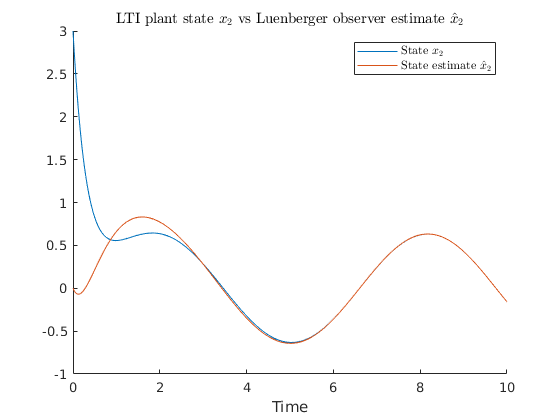

figure
hold on
plot(t_luen, x_luen(:,2));
plot(t_luen, x_hat_luen(:,2));
title('LTI plant state $x_2$ vs Luenberger observer estimate $\hat{x}_2$', "Interpreter",'latex');
xlabel('Time');
legend('State $x_2$', 'State estimate $\hat{x}_2$', "Interpreter",'latex');

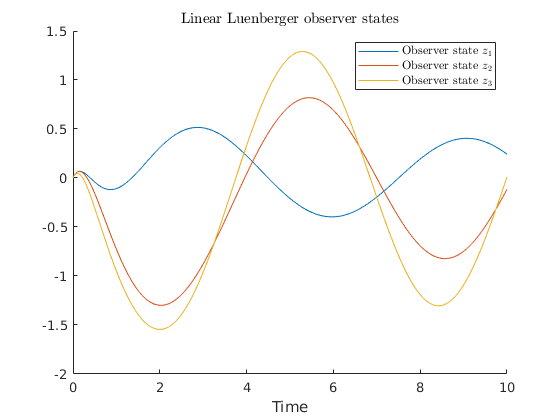

figure
hold on
plot(t_luen, z(:,1));
plot(t_luen, z(:,2));
plot(t_luen, z(:,3));
title('Linear Luenberger observer states', "Interpreter",'latex');
xlabel('Time');
legend('Observer state $z_1$', 'Observer state $z_2$', 'Observer state $z_3$', "Interpreter",'latex');

#### Corresponding output-error injection observer

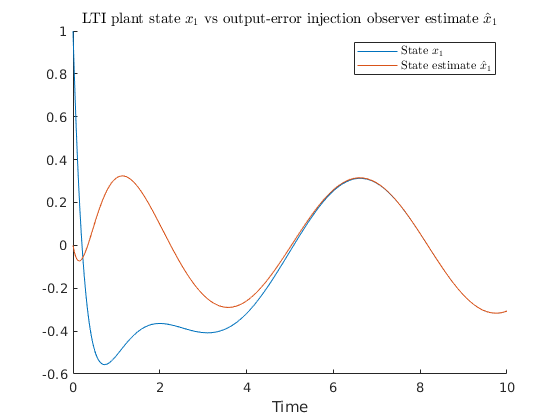

% Obtain corresponding L matrix
L = computeLFromLuenberger(T_star, F);

% Simulate system together with output-error injection observer
[t_oe, x_hat_oe, x_oe] = estimateLinearXOutputError(A,B,C,L,x0,tsim,u);

% Plot output-error injection observer results
figure
hold on
plot(t_oe, x_oe(:,1));
plot(t_oe, x_hat_oe(:,1));
title('LTI plant state $x_1$ vs output-error injection observer estimate $\hat{x}_1$', "Interpreter",'latex');
xlabel('Time');
legend('State $x_1$', 'State estimate $\hat{x}_1$', "Interpreter",'latex');

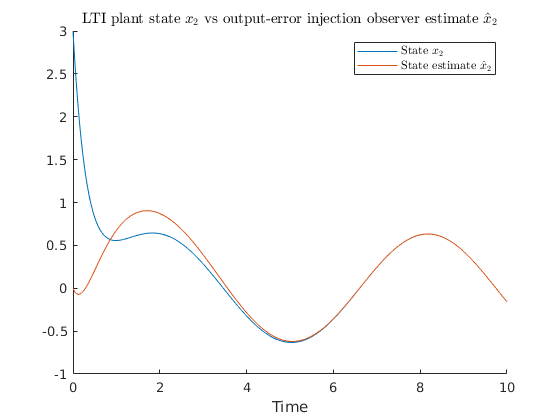

figure
hold on
plot(t_oe, x_oe(:,2));
plot(t_oe, x_hat_oe(:,2));
title('LTI plant state $x_2$ vs output-error injection observer estimate $\hat{x}_2$', "Interpreter",'latex');
xlabel('Time');
legend('State $x_2$', 'State estimate $\hat{x}_2$', "Interpreter",'latex');

### Example 2: Train neural network to estimate nonlinear Luenberger transformation of autonomous nonlinear system, and use it to generate state estimates.

#### Clear the workspace

clear all
close all

#### Specify plant parameters

% Plant model
f = @(x) [x(2).^3; -x(1);];
g = @(x) [0;0];
h = @(x) x(1);

% System test input
u0 = @(t) 0;

% System model dimension
dimx = 2;

#### Specify Luenberger observer

% Choose eigenvalues as roots of Bessel filter
[b,a] = besself(3,2*pi);
eigen = roots(a);

% Generate D matrix and specify F matrix
D = generateLuenbergerD([eigen(1) eigen(2) eigen(3)]);
F = [1;1;1;];

#### Specify simulation training parameters

% Number of simulations
nsims = 10;

% Length of simulations
tsim = 40;

% Length of time step to store results as
dt = 1e-2;

% Array of initial conditions
w0_array = zeros(dimx + size(D,2),nsims);
for idx=1:nsims
    w0_array(1,idx) = 0.1*idx;
end

#### Specify neural network parameters and learn Luenberger transformation

% Neural network parameters declaration
hidden_layers_size_arr = [25,25];
bias_connect = [1;0;0;];

% Obtain T_star
T_star_net = computeNonlinearLuenbergerTnn(f,g,h,dimx,u0,D,F,w0_array,nsims,tsim,dt,hidden_layers_size_arr,bias_connect);

#### Use trained neural network to implement observer

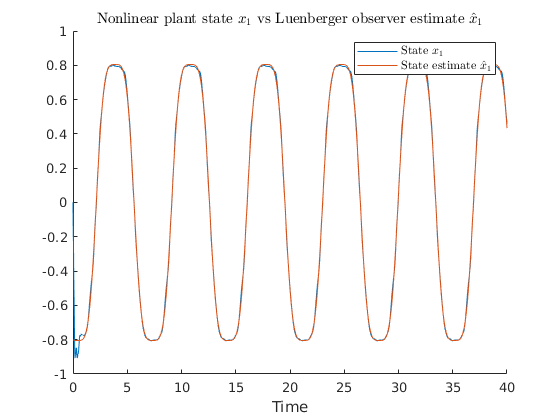

% Set initial conditions for plant randomly
w0_test = [rand(1) - 1; rand(1) - 1;0;0;0;];

% Simulate plant and Luenberger observer
[tq_test,w_test] = performMultipleLuenbergerSimulations(f,g,h,dimx,u0,D,F,w0_test,1,tsim,dt);

% Initialize state estimate storage array
x_hat = zeros(length(tq_test),2);

% Find state estimates using estimated Luenberger transformation
for jdx=1:length(tq_test)
    x_hat(jdx,:) = T_star_net(w_test(jdx,3:5)');
end

% Plot results
figure
hold on
plot(tq_test,x_hat(:,1));
plot(tq_test,w_test(:,1));
title('Nonlinear plant state $x_1$ vs Luenberger observer estimate $\hat{x}_1$', "Interpreter", 'latex');
xlabel('Time');
legend('State $x_1$', 'State estimate $\hat{x}_1$', "Interpreter", 'latex');

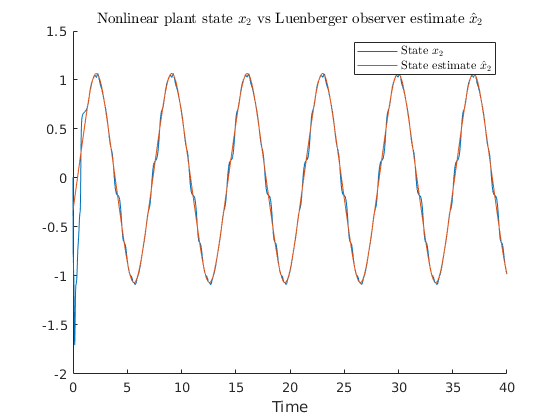

figure
hold on
plot(tq_test,x_hat(:,2));
plot(tq_test,w_test(:,2));
title('Nonlinear plant state $x_2$ vs Luenberger observer estimate $\hat{x}_2$',"Interpreter",'latex');
xlabel('Time');
legend('State $x_2$', 'State estimate $\hat{x}_2$', "Interpreter", 'latex');

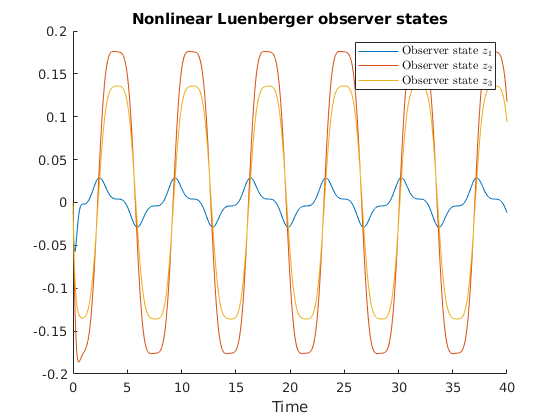

figure
hold on
plot(tq_test,w_test(:,3));
plot(tq_test, w_test(:,4));
plot(tq_test,w_test(:,5));
title('Nonlinear Luenberger observer states');
xlabel('Time');
legend('Observer state $z_1$', 'Observer state $z_2$', 'Observer state $z_3$', "Interpreter", 'latex');